# **CA#2 **

# Sogol Goodarzi 

# 810198467

# **Part(1): Raised-Cosine Pulse Generation**

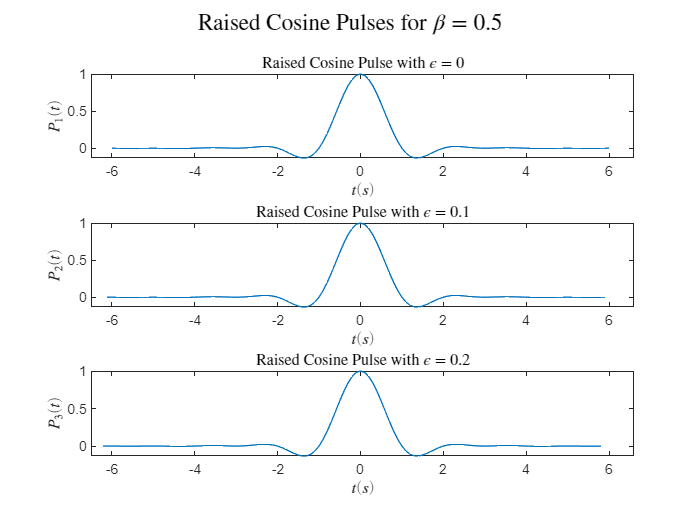

clear;
close all
beta1 = 0.5;
T = 1;
fs = 10;
delta_t = T/fs;
Errors = [0,0.1,0.2];
L = fs*T;
for i=1:3
    sampling_error(i) = Errors(i)*T;
    t(i,1:12*T*L+1) = (-6*L:6*L)/fs-sampling_error(i);
    p(i,1:12*T*L+1) = sinc(t(i,:)/T).*(cos(pi*beta1*t(i,:)/T)./(1-(2*beta1*t(i,:)/T).^2));
    p(i,find(t(i,:)==T/(2*beta1))) = pi/4*sinc(1/(2*beta1));
    p(i,find(t(i,:)==-T/(2*beta1))) = pi/4*sinc(1/(2*beta1));
end
figure();
subplot(3,1,1);
plot(t(1,:),p(1,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_1(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0$",Interpreter="latex");
xlim([-6.5,6.6]);
subplot(3,1,2);
plot(t(2,:),p(2,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_2(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0.1$",Interpreter="latex");
xlim([-6.5,6.6]);
subplot(3,1,3);
plot(t(3,:),p(3,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_3(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0.2$",Interpreter="latex");
xlim([-6.5,6.6]);
sgtitle("Raised Cosine Pulses for $\beta=0.5$",Interpreter="latex");

# **Part(2): Transmitted Signal Generation**

N = 1e5;
bits = randi([0,1],[1,N]);
modulated_symbols = bits;
modulated_symbols(find(bits==0)) = -1;
modulated_symbols(find(bits==1)) = 1;
temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));
transmitted_signal1 = conv(temp0,p(1,:));
transmitted_signal2 = conv(temp0,p(2,:));
transmitted_signal3 = conv(temp0,p(3,:));

# **Part(3): AWGN Channel Modeling**

SNR_dB = 0:10;
% SNR = db2mag(SNR_dB);
SNR = 10.^(SNR_dB./10);
etha = 1./SNR;
len = length(transmitted_signal1);
Noise = [];
for i=1:length(etha)
    Noise = [Noise ; sqrt(etha(i)/2)*randn([1,len])];
end
transmitted_signal = [transmitted_signal1;transmitted_signal2;transmitted_signal3];
for n=1:3
    for i=1:length(etha)
        received_signal(i,:,n) = transmitted_signal(n,:) + Noise(i,:);
    end 
end 

# **Part(4): Symbol Revelation**

T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples = received_signal(:,T_sampling,:);
treshold = 0;
detected_symbols = samples;
detected_symbols(find(samples > treshold)) = 1;
detected_symbols(find(samples < treshold)) = -1;

# **Part(5): Error Probability Calculation**

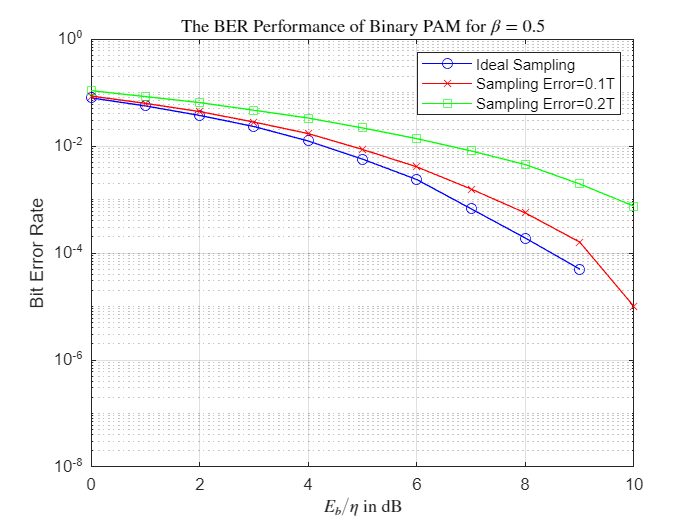

comparison_vec = detected_symbols == modulated_symbols;
for n=1:3
    for i=1:length(etha)
        pe(n,i) = 1-sum(comparison_vec(i,:,n))/length(samples);
    end
end
figure
semilogy(SNR_dB,pe(1,:),'ob-');
grid on
hold on 
semilogy(SNR_dB,pe(2,:),'xr-');
semilogy(SNR_dB,pe(3,:),'sg-');
legend("Ideal Sampling","Sampling Error=0.1T","Sampling Error=0.2T");
xlabel("$E_b/\eta$ in dB",'Interpreter','latex');
ylabel("Bit Error Rate");
ylim([1e-8,1]);
title("The BER Performance of Binary PAM for $\beta=0.5$",Interpreter="latex");
hold off

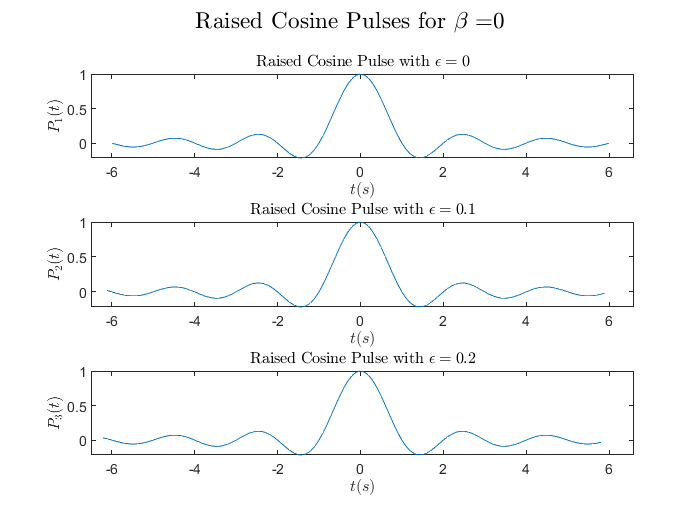

figure
beta2 = 0;
error_plot(beta2)

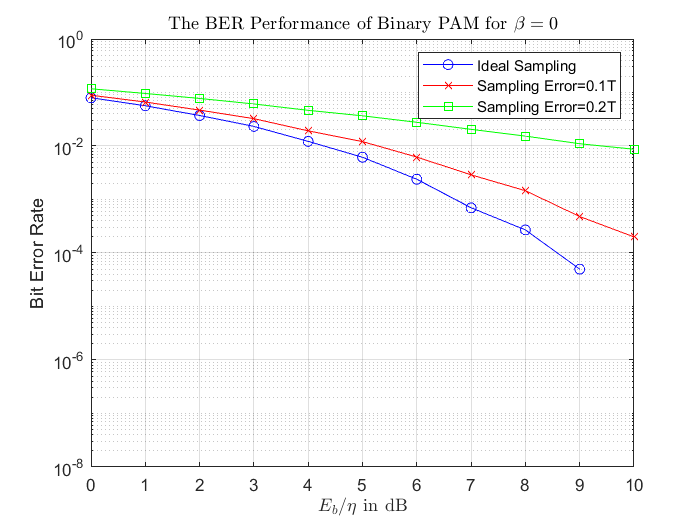

title("The BER Performance of Binary PAM for $\beta=0$",Interpreter="latex");

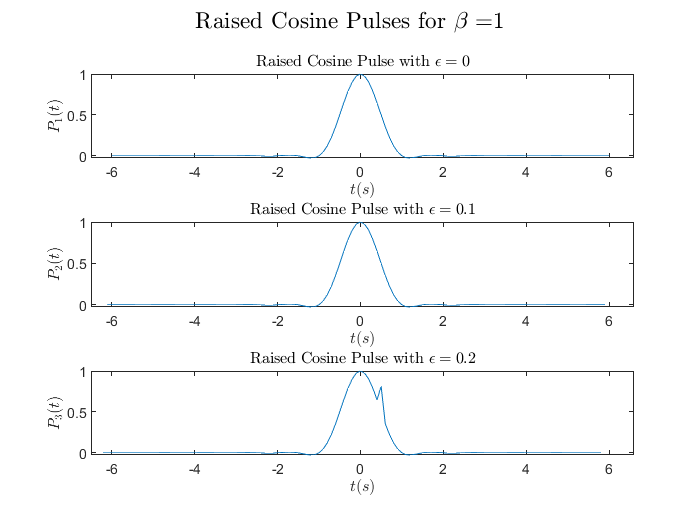

figure
beta3 = 1;
error_plot(beta3)

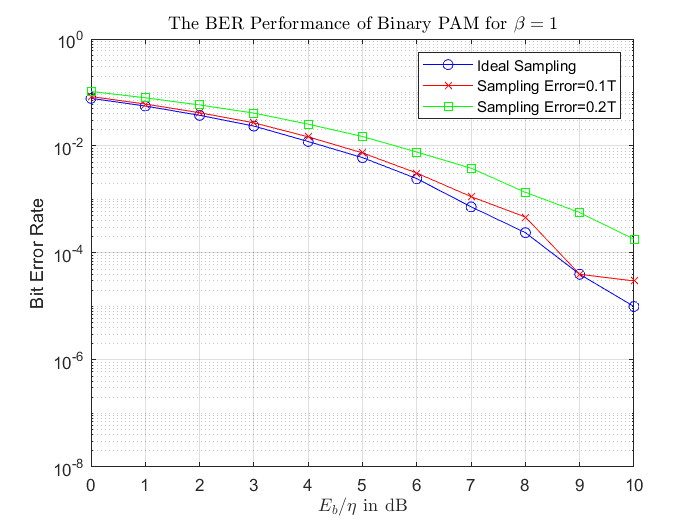

title("The BER Performance of Binary PAM for $\beta=1$",Interpreter="latex");

# **Function **

function error_plot(beta)
T = 1;
fs = 10;
delta_t = T/fs;
Errors = [0,0.1,0.2];
L = fs*T;
for i=1:3
    sampling_error(i) = Errors(i)*T;
    t(i,1:12*T*L+1) = (-6*L:6*L)/fs-sampling_error(i);
    p(i,1:12*T*L+1) = sinc(t(i,:)/T).*(cos(pi*beta*t(i,:)/T)./(1-(2*beta*t(i,:)/T).^2));
    p(i,find(t(i,:)==T/(2*beta))) = pi/4*sinc(1/(2*beta));
    p(i,find(t(i,:)==-T/(2*beta))) = pi/4*sinc(1/(2*beta));
end
ind = find(abs(t(3,:)) == T/(2*beta));
if (beta==1) ind = [ind,68]; end
figure;
subplot(3,1,1);
plot(t(1,:),p(1,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_1(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0$",Interpreter="latex");
xlim([-6.5,6.6]);
subplot(3,1,2);
plot(t(2,:),p(2,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_2(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0.1$",Interpreter="latex");
xlim([-6.5,6.6]);
subplot(3,1,3);
plot(t(3,:),p(3,:));
xlabel("$t(s)$",Interpreter="latex");
ylabel("$P_3(t)$",Interpreter="latex");
title("Raised Cosine Pulse with $\epsilon=0.2$",Interpreter="latex");
xlim([-6.5,6.6]);
sgtitle(['Raised Cosine Pulses for $\beta=$',num2str(beta)],'Interpreter','latex');
N = 1e5;
bits = randi([0,1],[1,N]);
modulated_symbols = bits;
modulated_symbols(find(bits==0)) = -1;
modulated_symbols(find(bits==1)) = 1;
temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));
transmitted_signal1 = conv(temp0,p(1,:));
transmitted_signal2 = conv(temp0,p(2,:));
transmitted_signal3 = conv(temp0,p(3,:));
SNR_dB = 0:10;
SNR = 10.^(SNR_dB./10);
etha = 1./SNR;
len = length(transmitted_signal1);
Noise = [];
for i=1:length(etha)
    Noise = [Noise ; sqrt(etha(i)/2)*randn([1,len])];
end
transmitted_signal = [transmitted_signal1;transmitted_signal2;transmitted_signal3];
for n=1:3
    for i=1:length(etha)
        received_signal(i,:,n) = transmitted_signal(n,:) + Noise(i,:);
    end 
end 
T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples = received_signal(:,T_sampling,:);
treshold = 0;
detected_symbols = samples;
detected_symbols(find(samples > treshold)) = 1;
detected_symbols(find(samples < treshold)) = -1;
comparison_vec = detected_symbols == modulated_symbols;
for n=1:3
    for i=1:length(etha)
        pe(n,i) = 1-sum(comparison_vec(i,:,n))/length(samples);
    end
end
figure
semilogy(SNR_dB,pe(1,:),'ob-');
grid on
hold on 
semilogy(SNR_dB,pe(2,:),'xr-');
semilogy(SNR_dB,pe(3,:),'sg-');
legend("Ideal Sampling","Sampling Error=0.1T","Sampling Error=0.2T");
xlabel("$E_b/\eta$ in dB",Interpreter="latex");
ylabel("Bit Error Rate");
ylim([1e-8,1]);
hold off
end